# Transverse-shear locking due incompatible discretization spaces

Using the same polynomials basis functions for the discretization of the vertical displacement and rotation fields leads to a discretization space for the transverse shear forces that by construction does not contain zero transverse shear forces, namely: $\gamma = \frac{\text{d}w}{\text{d}x} + \beta = \sum_{i=1}^n \overbrace{\frac{\text{d}N_i^w(\xi)}{\text{d}x}}^{\text{constant}} w_i + \sum_{i = 1}^n \overbrace{N_i^{\beta}(\xi)}^{\text{linear}} \beta_i$

This fact is a direct consequence of the summation of piecewise polynomial functions with their derivatives which cannot be identically zero. The residual transverse-shear strains are then scaled by the material and geometric parameters to obtain the transverse-shear forces, namely:


$$Q = \alpha G A \gamma = \alpha G A \overbrace{\left(\frac{\text{d} w}{\text{d} x} + \beta\right)}^{\gamma}$$


which amplifies this numerical effect disproportionally as the thickness goes to zero $t \rightarrow 0$ (negligible shear deformations) as compared to the bending part that is scaled by $Eb t^3/12$.This is know as transverse shear-locking for shear-deformable thin-walled structures. Increasing the polynomial order reduces this effect but does not entirely remove it. 

In this section the transverse-shear force $Q$ is computed using linear and quadratic one-dimensional elements along with their counterparts when using selective-reduced integration along the beam. The solutions are compared to the transverse shear force distribution when using the Euler-Bernoulli beam formulation.

Go to [THIS](matlab:open('./main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) Section in the main driver script *Transverse-Shear Locking in Timoshenko beam elements - Cantilever Beam Subject to Vertical Distributed Load*

Go to [NEXT](matlab:open('./main_Chapter42_TimoshenkoBeamLocking_ConvergenceStudy.mlx')) Section *Convergence study on transverse shear-locking*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

vars = ["mshL1" "mshL2" "numElL1" "NL1" "NL2" "propStr" "numPts"];
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter3_Locking_TimoshenkoBeam.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Initialization of the evaluation points along the beam where the shear forces are computed

Definition of the vertical deflection $w(\xi)$, rotation $\beta$, position $X(\xi)$, jacobian $J (\xi) = \frac{\text{d} X}{\text{d} \xi}$, the derivative of the vertical deflection with respect to the physical space $\frac{\text{d} w (\xi)}{\text{d} x}$ and shear force $Q(\xi)$ function fields

syms wL1(xi) wL1RI(xi) wL2(xi) wL2RI(xi) betaL1(xi) betaL1RI(xi) ...
    betaL2(xi) betaL2RI(xi) posVctL1(xi) posVctL2(xi) ...
    jacobianMtxL1(xi) jacobianMtxL2(xi) dwdxL1(xi) dwdxL1RI(xi) ...
    dwdxL2(xi) dwdxL2RI(xi) QL1(xi) QL1RI(xi) QL2(xi) QL2RI(xi) ...
    phi1(xi) phi2(xi) phi3(xi) phi4(xi) Phi1(X) Phi2(X) Phi3(X) ...
    Phi4(X) Phi(X) wEB(X) QEB(X)

Computation the bounding box of the Finite Element mesh and generate a sequence of sampling points onto which to compute the shear forces:

boundingBox = [min(mshL1.nodes(:, 1)) max(mshL1.nodes(:, 1))];
XVct = linspace(boundingBox(1), boundingBox(2), numPts);
QPts = zeros(numPts, 6);

## Loop over all the sampling points for the computation of the transverse-shear forces

for ii = 1:numPts

### Find the element to which the evaluation point belongs

    el = nan;
    for jj = 1:numElL1

Set-up the position vector corresponding to the current element is constructed as $x(\xi) = \sum_{i = 1}^2 N_{i}(\xi) x_i^{\text{e}}$ for both the linear and the bilinear mesh

        posVctL1(xi) = NL1*mshL1.nodes(mshL1.elements(jj, :));
        posVctL2(xi) = NL2*mshL2.nodes(mshL2.elements(jj, :));

Construct the inverse position vector corresponding to the current element $\xi(x) = x(\xi)^{-1}$

        posVctInv = finverse(posVctL1);

Compute the parametric coordinate of the evaluation point in the current element using the element's inverse parametric representation

        xiParam = posVctInv(XVct(ii));

Check whether the computed parametric coordinate $\xi$ is within the closed space $[-1,1]$. If it is, then the evaluation point belongs to the current element, otherwise not

        if xiParam >= -1 && xiParam <= 1
            el = jj;
            break;
        end

    end

### Verification of the element's validity containing the current point

    if isnan(el)
        error("The point with coordinate %d was found " + ...
            "in no element in the mesh", x(ii));
    end

### Set-up the Element Freedom Table (EFT) for the one-dimensional linear element

    EFTL1 = [2*mshL1.elements(el, :) - 1; 2*mshL1.elements(el, :)];
    EFTL1 = EFTL1(:);

### Set-up the Element Freedom Table (EFT) for the two-dimensional quadratic element

    EFTL2 = [2*mshL2.elements(el, :) - 1; 2*mshL2.elements(el, :)];
    EFTL2 = EFTL2(:);

### Setup of the expressions for the vertical deflection and rotation fields for the one-dimensional linear element

    wL1(xi) = NL1*uL1(EFTL1(1:2:end), 1); % w(x)
    betaL1(xi) = NL1*uL1(EFTL1(2:2:end), 1); % β(x)

### Setup of the expressions for the vertical deflection and rotation fields for the one-dimensional linear element with the selective-reduced integration

    wL1RI(xi) = NL1*uL1RI(EFTL1(1:2:end), 1); % w(x)
    betaL1RI(xi) = NL1*uL1RI(EFTL1(2:2:end), 1); % β(x)

### Setup of the expressions for the vertical deflection and rotation fields for the one-dimensional quadratic element

    wL2(xi) = NL2*uL2(EFTL2(1:2:end), 1); % w(x)
    betaL2(xi) = NL2*uL2(EFTL2(2:2:end), 1); % β(x)

### Setup of the expressions for the vertical deflection and rotation fields for the one-dimensional quadratic element with the selective-reduced integration

    wL2RI(xi) = NL2*uL2RI(EFTL2(1:2:end), 1); % w(x)
    betaL2RI(xi) = NL2*uL2RI(EFTL2(2:2:end), 1); % β(x)

### Computation of the derivatives of the vertical deflection and rotation fields with respect to the physical space

To compute the derivatives of the basis functions with respect to the physical space given that they are defined in the parametric space, the chain rule in one-dimensiona can be used, namely:


$$\frac{\text{d} w}{\text{d} x} = \frac{\text{d} w}{\text{d} \xi} \overbrace{\frac{\text{d} \xi}{\text{d} x}}^{J^{-1}}$$


The inverse of the Jacobian matrix for the one-dimensional elements is given by the following expression:


$$J^{-1}(\xi) = \frac{\text{d} \xi}{\text{d} x}$$


i.e. it is simply a scalar quantity. The Jacobian matrix in this case can be computed using function [`jacobian`](https://www.mathworks.com/help/symbolic/sym.jacobian.html) in MATLAB:

    jacobianMtxL1 = jacobian(posVctL1, xi);
    jacobianMtxL2 = jacobian(posVctL2, xi);

... setting-up the derivatives of the vertical deflection field corresponding to the one-dimensional linear elements based on full integration with respect to the physical space

    dwdxL1(xi) = transpose(inv(jacobianMtxL1(xi)))*diff(wL1, xi);

... setting-up the derivatives of the vertical deflection field corresponding to the one-dimensional linear elements based on selective-reduced integration with respect to the physical space

    dwdxL1RI(xi) = transpose(inv(jacobianMtxL1(xi)))*diff(wL1RI, xi);

... setting-up the derivatives of the vertical deflection field corresponding to the one-dimensional quadratic elements based on full integration with respect to the physical space

    dwdxL2(xi) = transpose(inv(jacobianMtxL2(xi)))*diff(wL2, xi);

... setting-up the derivatives of the vertical deflection field corresponding to the one-dimensional quadratic elements based on selective-reduced integration with respect to the physical space

    dwdxL2RI(xi) = transpose(inv(jacobianMtxL2(xi)))*diff(wL2RI, xi);

### Computation of the resultant transverse-shear force at the evaluation point

The resultant transverse shear force is given in this case by the expression $Q (\xi) = \alpha G A \gamma (\xi) = \alpha G A \overbrace{ \left( \frac{\text{d} w (\xi)}{\text{d} x} + \beta(\xi)\right)}^{\gamma(\xi)}$

... corresponding to the one-dimensional linear elements based on full integration with respect to the physical space

    QL1(xi) = propStr.alpha*propStr.G*propStr.A*(dwdxL1(xi) + betaL1(xi));
    checkDistributions_L1 = false; % enable if you want to observe the analytical expressions for the different constituents forming the shear strain
    if checkDistributions_L1
        if ii == ceil(numPts/2)
            figure
            fplot([dwdxL1, betaL1], [mshL1.nodes(mshL1.elements(el, 1)), ...
                mshL1.nodes(mshL1.elements(el, 2))]);
            fprintf("w' = ")
            displayFormula(string(simplify(dwdxL1)))
            fprintf("\n")
            fprintf("beta = ")
            displayFormula(string(simplify(betaL1)))
            fprintf("\n")
            legend("w'", "\beta")
            xlabel("x");
            ylabel("w', \beta")
            legend("w'", "\beta")
            title("Linear two-noded discretization")
        end
    end
    QPts(ii, 1) = double(QL1(xiParam));

... corresponding to the one-dimensional linear elements based on selective-reduced integration with respect to the physical space

    QL1RI(xi) = propStr.alpha*propStr.G*propStr.A*...
        (dwdxL1RI(xi) + betaL1RI(xi));
    QPts(ii, 2) = double(QL1RI(xiParam));

... corresponding to the one-dimensional quadratic elements based on full integration with respect to the physical space

    QL2(xi) = propStr.alpha*propStr.G*propStr.A*(dwdxL2(xi) + betaL2(xi));

Enable the checkbox below if you want to observe the analytical expressions for the different constituents forming the shear strain

    checkDistributions_L2 = true;
    if checkDistributions_L2
        if ii == ceil(numPts/2)
            figure
            fplot([dwdxL2, betaL2], [mshL2.nodes(mshL2.elements(el, 1)), ...
                mshL2.nodes(mshL2.elements(el, 2))]);
            fprintf("w' = ")
            displayFormula(string(simplify(dwdxL2)))
            fprintf("\n")
            fprintf("beta = ")
            displayFormula(string(simplify(betaL2)))
            fprintf("\n")
            legend("w'", "\beta")
            xlabel("x");
            ylabel("w', \beta")
            legend("w'", "\beta")
            title("Quadratic three-noded discretization")
        end
    end
    QPts(ii, 3) = double(QL2(xiParam));

... corresponding to the one-dimensional quadratic elements based on selective-reduced integration with respect to the physical space

    QL2RI(xi) = propStr.alpha*propStr.G*propStr.A*...
        (dwdxL2RI(xi) + betaL2RI(xi));
    QPts(ii, 4) = double(QL2RI(xiParam));

### Set-up the displacement field as a function using the Hermitian basis functions and the solution of the problem by means of the Euler-Bernoulli beam theory

The interpolation of the [Euler-Bernoulli](https://en.wikipedia.org/wiki/Euler%E2%80%93Bernoulli_beam_theory) solution using the [Hermitian third-order basis functions](https://en.wikipedia.org/wiki/Cubic_Hermite_spline)is given as follows:


$$w(X) = N_1(X)w_i + (X_j - X_i)N_2(X)\phi_i + N_3(X)w_j + (X_j - X_i)N_4(X) \phi_j$$


    phi1(xi) = 2*xi^3 - 3*xi^2 + 1;
    phi2(xi) = diff(mshL1.nodes(mshL1.elements(el, :)))*...
        (xi.^3 - 2*xi.^2 + xi);
    phi3(xi) = -2*xi.^3 + 3*xi.^2;
    phi4(xi) = diff(mshL1.nodes(mshL1.elements(el, :)))*...
        (xi.^3 - xi.^2);
    Phi1(X) = subs(phi1, xi, (X - mshL1.nodes(mshL1.elements(el, 1))/...
        diff(mshL1.nodes(mshL1.elements(el, :)))));
    Phi2(X) = subs(phi2, xi, (X - mshL1.nodes(mshL1.elements(el, 1))/ ...
        diff(mshL1.nodes(mshL1.elements(el, :)))));
    Phi3(X) = subs(phi3, xi, (X - mshL1.nodes(mshL1.elements(el, 1))/ ...
        diff(mshL1.nodes(mshL1.elements(el, :)))));
    Phi4(X) = subs(phi4, xi, (X - mshL1.nodes(mshL1.elements(el, 1))/ ...
        diff(mshL1.nodes(mshL1.elements(el, :)))));
    Phi(X) = [Phi1(X) Phi2(X) Phi3(X) Phi4(X)];
    wEB(X) = Phi(X)*uEB(EFTL1, 1);

### Computation of the resultant transverse shear forces corresponding to the Euler-Bernoulli beam theory

The resultant shear forces corresponding to the Euler-Bernoulli beam theory are given by $Q = -\frac{\text{d} }{\text{d} x} \left( E I \frac{\text{d}^2 w}{\text{d} x^2} \right)$, see [here](https://en.wikipedia.org/wiki/Euler%E2%80%93Bernoulli_beam_theory) for more details.

    QEB(X) = - propStr.E*propStr.I*diff(wEB(X), X, 3);
    QPts(ii, 5) = double(QEB(xiParam));

### Computation of the analytical shear force for the particular problem corresponding to the Timoshenko beam theory

    QPts(ii, 6) = double(QEx(XVct(ii)));

end

w' = 

$$\frac{-986519169576243\,\xi }{9007199254740992}-\frac{18262865179418223}{18014398509481984}$$

beta = 

$$\frac{987455918298733\,\xi }{9007199254740992}-\frac{36402152428685\,\xi^{2}}{9007199254740992}+\frac{4568504699730591}{4503599627370496}$$

## Plot the shear force along the x-directions at the mid-width of the plate

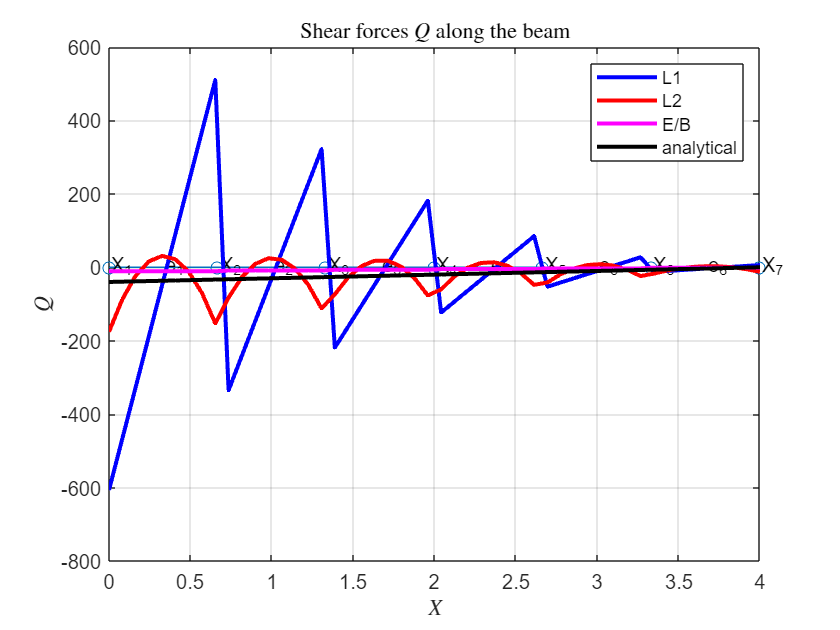

plotMesh1d(mshL1);
hold on;
plot(XVct, QPts(:, 1), 'b-', 'LineWidth', 2)
plot(XVct, QPts(:, 3), 'r-', 'LineWidth', 2)
plot(XVct, QPts(:, 5), 'm-', 'LineWidth', 2)
plot(XVct, QPts(:, 6), 'k-', 'LineWidth', 2)
hold off;
legend("", "L1", "L2", "E/B", "analytical")
grid on;
xlabel("$X$", Interpreter="latex")
ylabel("$Q$", Interpreter="latex")
title("Shear forces $Q$ along the beam", Interpreter="latex")

  **Try**

Plot the distribution of the transverse-shear forces also for the elements for which selective-reduced integration is applied:

 **Reflect**

What do you observe about the underlying distributions? Is the transverse shear force correctly captured by means of the elements for which  selective-reduced integration is applied